close('all'); clear; clc;

load('ctftmod.mat');

错误使用 load
找不到文件或目录 'ctftmod.mat'。

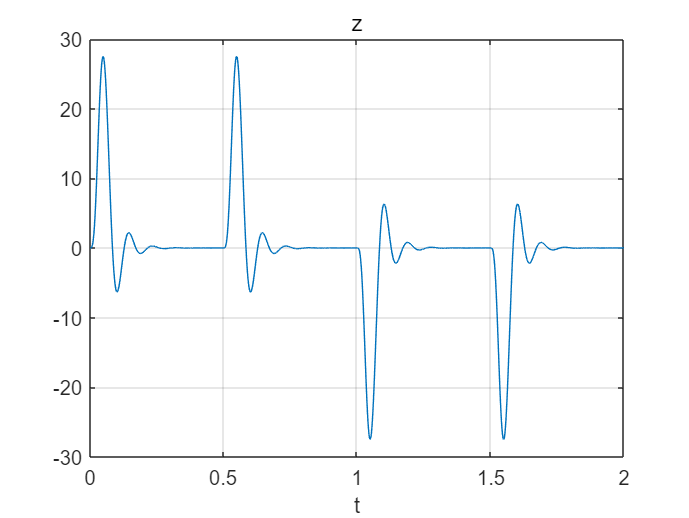


%% a
z = [dash dash dot dot];

figure;
plot(t, z); grid('on');
title('z'); xlabel('t');

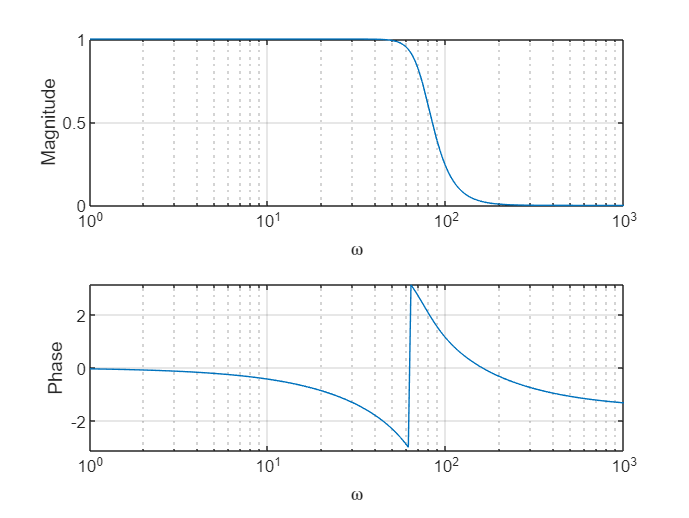



%% b
[h, wout] = freqs(bf, af);

figure;
subplot(2,1,1);
semilogx(wout, abs(h)); grid('on');
axis([xlim 0 1]);
xlabel('\omega'); ylabel('Magnitude');
subplot(2,1,2);
semilogx(wout, angle(h)); grid('on');
axis([xlim -pi pi]);
xlabel('\omega'); ylabel('Phase');

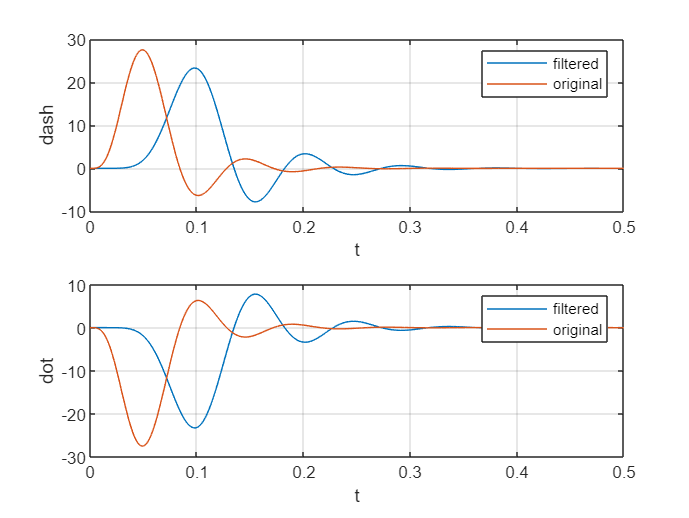



%% c
ydash = lsim(bf, af, dash, t(1:length(dash)));
ydot = lsim(bf, af, dot, t(1:length(dot)));

figure;
subplot(2,1,1);
plot(t(1:length(dash)), ydash, t(1:length(dash)), dash); grid('on');
xlabel('t'); ylabel('dash'); legend('filtered', 'original')
subplot(2,1,2);
plot(t(1:length(dot)), ydot, t(1:length(dot)), dot); grid('on');
xlabel('t'); ylabel('dot'); legend('filtered', 'original')

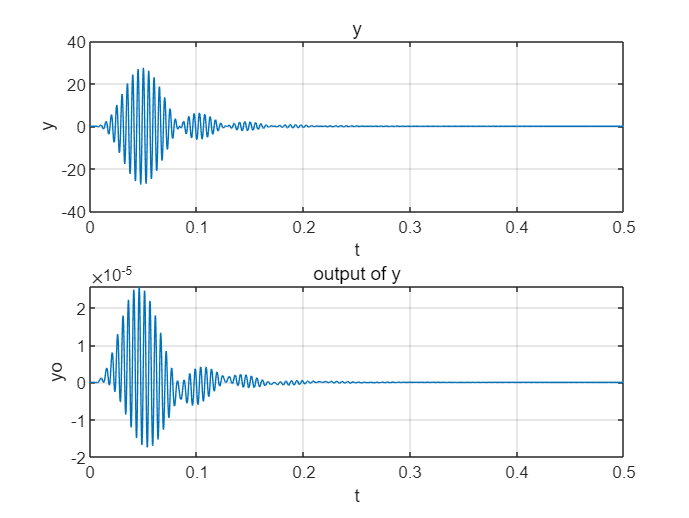

% d
y = dash .* cos(2 * pi * f1 * t(1 : length(dash)));
subplot(2, 1, 1);
plot(t(1 : length(dash)), y);
grid on;
xlabel("t");
ylabel("y");
title("y")

yo = lsim(bf, af, y, t(1:length(dash)));
subplot(2, 1, 2);
plot(t(1 : length(dash)), yo);
grid on;
xlabel("t");
ylabel("yo");
title("output of y")

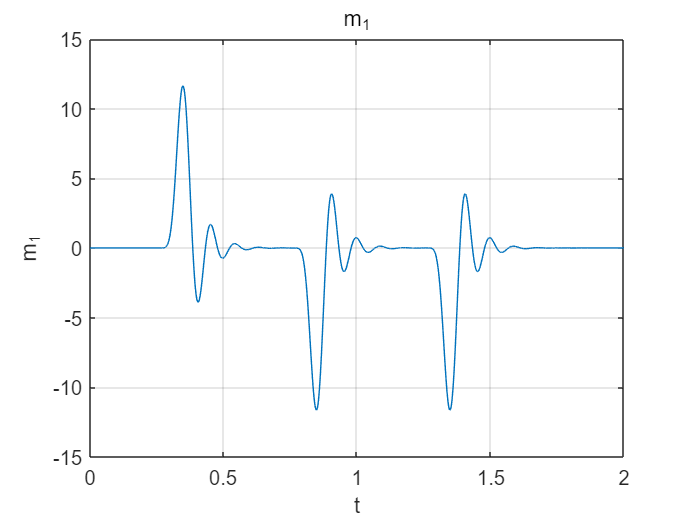

% e
close all;
m1 = lsim(bf, af, x .* cos(2 * pi * f1 * t), t);
% m1_ori = m1 ./ cos(2 * pi * f1 * t);
plot(t, m1);
grid on;
xlabel("t");
ylabel("m_1");
title("m_1");

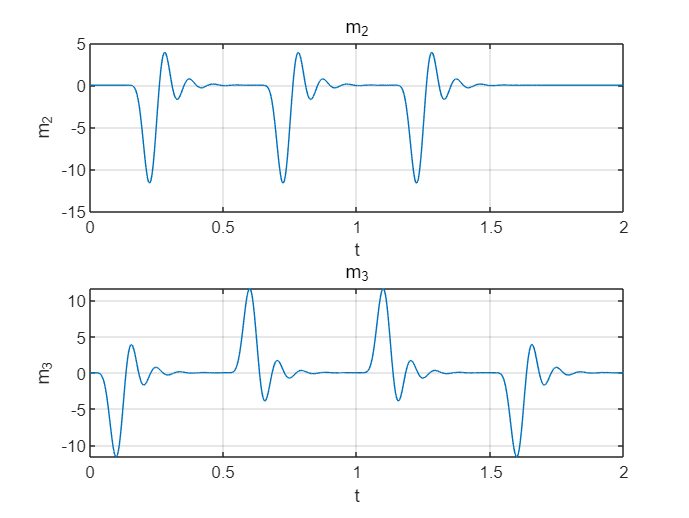

% f
subplot(2, 1, 1);
m2 = lsim(bf, af, x .* sin(2 * pi * f2 * t), t);
plot(t, m2);
grid on;
xlabel("t");
ylabel("m_2");
title("m_2");

subplot(2, 1, 2);
m3 = lsim(bf, af, x .* sin(2 * pi * f1 * t), t);
plot(t, m3);
grid on;
xlabel("t");
ylabel("m_3");
title("m_3");

close all;
y1 = lsim(bf, af, x .* cos(2 * pi * f1 * t), t)

y1 =          0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


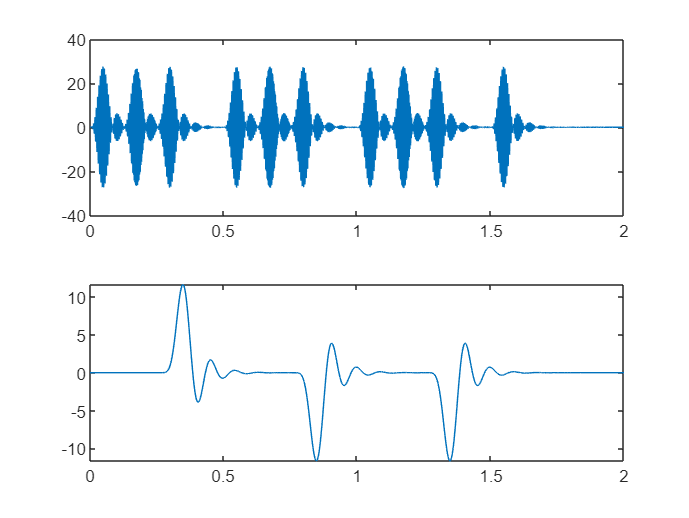

subplot(2, 1, 1)
plot(t, x);
subplot(2, 1, 2)
plot(t, y1);